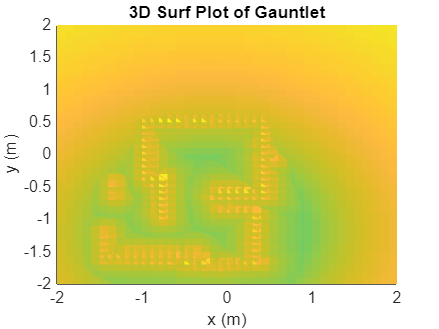


load(fullfile(pwd,"globalCleaned/bglobalCleaned1.mat"));
load(fullfile(pwd,"globalCleaned/globalCleaned1.mat"));
load(fullfile(pwd,"globalCleaned/globalCleaned2.mat"));
load(fullfile(pwd,"globalCleaned/globalCleaned6.mat"));
load(fullfile(pwd,"globalCleaned/globalCleaned7.mat"));

[x, y] = meshgrid(-2:0.1:2, -2:0.1:2);
hold on;
z_final = 0;
for id1 = 1:size(globalCleaned1, 2)
    x1 = globalCleaned1(1, id1);
    y1 = globalCleaned1(2, id1);
    z1 = -(log(sqrt((x-x1).^2 + (y-y1).^2)));
    surf(x, y, z1, 'EdgeColor','none');
    z_final = z_final - z1;
end

for id2 = 1:size(globalCleaned2, 2)
    x2 = globalCleaned2(1, id2);
    y2 = globalCleaned2(2, id2);
    z2 = -(log(sqrt((x-x2).^2 + (y-y2).^2)));
    surf(x, y, z2, 'EdgeColor','none');
    z_final = z_final - z2;
end

for id6 = 1:size(globalCleaned6, 2)
    x6 = globalCleaned6(1, id6);
    y6 = globalCleaned6(2, id6);
    z6 = -(log(sqrt((x-x6).^2 + (y-y6).^2)));
    surf(x, y, z6, 'EdgeColor','none');
    z_final = z_final - z6;
end
for id7 = 1:size(globalCleaned7, 2)
    x7 = globalCleaned7(1, id7);
    y7 = globalCleaned7(2, id7);
    z7 = -(log(sqrt((x-x7).^2 + (y-y7).^2)));
    surf(x, y, z7, 'EdgeColor','none');
    z_final = z_final - z7;
end

%Ploting ball as sink
zb = 4*(log(sqrt((x+0.25).^2 + (y+1.25).^2)));
z_final = z_final - (zb*50);
surf(x, y, zb, 'EdgeColor','none');
title('3D Surf Plot of Gauntlet');
xlabel('x (m)');
ylabel('y (m)');
hold off;

%surf(x, y, z_final, 'EdgeColor', 'none');

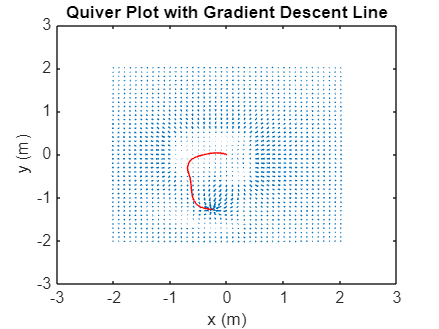

% Calculate the gradient of the potential field
[dx, dy] = gradient(z_final);
% Plot the quiver plot
figure;
quiver(x, y, dx, dy);
l = streamline(x, y, dx ,dy, 0, 0);
set(l, 'color', 'r')
xlabel('x (m)');
ylabel('y (m)');
title('Quiver Plot with Gradient Descent Line');
hold on;
[sinkdx, sinkdy] = gradient(zb);
%quiver(x, y, sinkdx, sinkdy);
totaldx = sinkdx + dx;
totaldy = sinkdy + dy;
hold off;

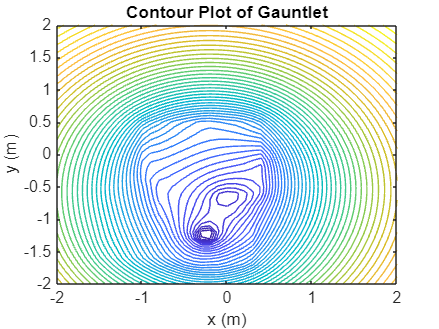

% Contour plot
z_final = z_final + (2*(zb*50));
contour(x,y, z_final, 50);
title('Contour Plot of Gauntlet');
xlabel('x (m)');
ylabel('y (m)');

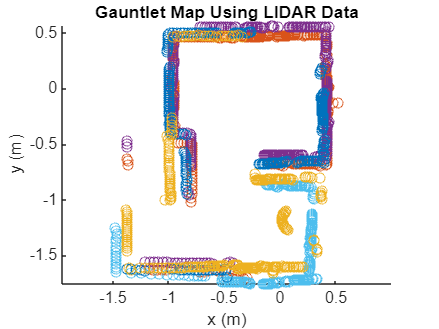

% Creating Gauntlet Map from LIDAR Data

allPlots = figure;
scatter(globalCleaned1(1,:), globalCleaned1(2,:), 'o');
        axis("equal");
        figure(allPlots);
        hold on;
        scatter(globalCleaned1(1,:), globalCleaned1(2,:), 'o');
        axis("equal");
             scatter(globalCleaned2(1,:), globalCleaned2(2,:), 'o');
        axis("equal");
        figure(allPlots);
        hold on;
        scatter(globalCleaned2(1,:), globalCleaned2(2,:), 'o');
        axis("equal");
         scatter(globalCleaned6(1,:), globalCleaned6(2,:), 'o');
        axis("equal");
        figure(allPlots);
        hold on;
        scatter(globalCleaned6(1,:), globalCleaned6(2,:), 'o');
        axis("equal");
         scatter(globalCleaned7(1,:), globalCleaned7(2,:), 'o');
        axis("equal");
        figure(allPlots);
        hold on;
        scatter(globalCleaned7(1,:), globalCleaned7(2,:), 'o');
        axis("equal");
        scatter(bglobalCleaned1(1,:), bglobalCleaned1(2,:), 'o');
        axis("equal");
        title("Gauntlet Map Using LIDAR Data")
        xlabel('x (m)')
        ylabel('y (m)')
        figure(allPlots);
        hold on;
        scatter(bglobalCleaned1(1,:), bglobalCleaned1(2,:), 'o');
        axis("equal");